clear

%% DEFINE THE PLANT INITIAL CONDITIONS

% Initial motor angle [radians]
theta_m_init = deg2rad(0);
% Initial link angle [radians]
theta_l_init = deg2rad(0);
% Initial motor velocity [radians/second]
thetadot_m_init = deg2rad(0);
% Initial link velocity [radians/second]
thetadot_l_init = deg2rad(0);
% Initial motor current [Amps]
Ia_init = 0;

% Initial conditions stacked as a 5x1 vector
init = [theta_m_init; theta_l_init; thetadot_m_init; thetadot_l_init; Ia_init];

%% DEFINE THE SENSOR PARAMETERS

% FOR VISION:
% > The frames per second [fps]
% > Allowed values: 25, 50, 100
vision_fps = 50;

% FOR ABSOLUTE ENCODER
% > Number of counts per revolution
absolute_encoder_counts_per_revolution = 4096;

% FOR POTENTIOMETER
% > Percentage linearity [percent]
potentiometer_linearity_percent = 20;

% FOR TACHOMETER
% > Number of counts per revolution
tachometer_counts_per_revolution = 2048;
% > Frequency of the velocity estimates
% > Allowed values: 10, 25, 50, 100
tachometer_output_frequency = 50;

% FOR GYROSCOPE
% > Variance of the noise that drives the drift process [rad/s^2]
gyro_sigma_drift = deg2rad(5);

Jl =0.001;
m =0.1;
g =9.81;
l =0.1;
Ks =1.75;

% Motor 1
Km =0.5369;
Jm =0.0021;
La =0.18*(10^(-3));
Ra = 2.6;

A=[0 0 1 0 ;0 0 0 1 ;(-Ks/Jm) (Ks/Jm) -((Km)^2/(Ra*Jm)) 0;(Ks/Jl) (-Ks/Jl-(m*g*l*cosd(30))/(Jl)) 0 0];
B=[0;0;Km/(Ra*Jm);0];
C=[1 0 0 0];
D=0;

## MPC

%% STATE AND INPUT SIZES
nx = size(A,2);
nu = size(B,2);

%% SPECIFY THE WEIGHTING MATRICES

% > for penalising each state
Wy = 1000;
% > for penalising the input
Wu = 0.1;
% > for penalising input changes
WDeltau = 0.1;
% > for penalising the terminal state
WyN = 0.1;

%% BUILD THE PLANT
% Specify the C and D
C_for_mpc = [ 0 , 1 , 0 , 0];
D_for_mpc = 0;
% Build the continuous-time plant
LTI_plant_continuous_time = ss(A,B,C_for_mpc,D_for_mpc);
% Convert to a discrete-time plant
sample_time = 1/50;
LTI_plant_discrete_time = c2d(LTI_plant_continuous_time, sample_time, 'zoh' );

%% OUTPUT VARIABLE SIZE
ny = size(C_for_mpc,1);

%% PUT THE WEIGHTINGS INTO A STRUCT
W = struct();
W.ManipulatedVariables     = Wu;
W.ManipulatedVariablesRate = WDeltau;
W.OutputVariables          = Wy;

%% SPECIFY THE MANIPULATED VARIABLE CONSTRAINTS
MV = struct();
MV.Min         = -6; %[Nm]
MV.Max         =  6; %[Nm]
MV.MinECR      = 0;
MV.MaxECR      = 0;
MV.RateMin     = -Inf;
MV.RateMax     = Inf;
MV.RateMinECR  = 0;
MV.RateMaxECR  = 0;
MV.Target      = 'nominal';
MV.Name        = 'T';
MV.Units       = 'Nm';
MV.ScaleFactor = 1;

%% SPECIFY THE OUTPUT VARIABLE CONSTRAINTS
OV = struct();
OV(1).Min         = deg2rad(10);
OV(1).Max         = deg2rad(50);
OV(1).MinECR      = 0.1;
OV(1).MaxECR      = 0.1;
OV(1).Name        = 'theta_l';
OV(1).Units       = 'radians';
OV(1).ScaleFactor = 1;

%% CREATE THE MPC OBJECT
prediction_horizon = 10;
control_horizon = prediction_horizon;
mpc_obj = mpc(LTI_plant_discrete_time, sample_time, prediction_horizon, control_horizon, W, MV, OV);

%% SET THE TERMINAL WEIGHT
% > For the output variables
terminal_setting_for_OV = struct();
terminal_setting_for_OV.Weight = WyN;
% > For the manipulated variables
terminal_setting_for_MV = struct();
terminal_setting_for_MV.Weight = W.ManipulatedVariables;
% > Call the function to set
setterminal(mpc_obj, terminal_setting_for_OV, terminal_setting_for_MV);

%% SET THE STATE ESTIMATOR
setEstimator(mpc_obj,'custom');

%% SET THE OUTPUT DISTURBANCE TO ZERO
setoutdist(mpc_obj,'model',ss(zeros(ny,1)));

%% CREATE THE MPC INITIAL STATE VARIABLE
% > Specify the initial condition for each state
theta_l_init     = deg2rad(15);
theta_m_init     = deg2rad(15);
theta_l_dot_init = deg2rad(0);
theta_m_dot_init = deg2rad(0);
% > Create the variable for the MPC block
mpc_initial_state = mpcstate(mpc_obj);

-->The "Model.Noise" property is empty. Assuming white noise on each measured output.


mpc_initial_state.Plant = [theta_l_init, theta_m_init, theta_l_dot_init, theta_m_dot_init];

%% DISPLAY THE MPC OBJECT
display(mpc_obj)

 
MPC object (created on 03-Nov-2023 22:43:36):
---------------------------------------------
Sampling time:      0.02 (seconds)
Prediction Horizon: 10
Control Horizon:    10

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  4 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  1 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Disturbance and Noise Models:
        Output disturbance model: user specified (type "getoutdist(mpc_obj)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: [10×1 double]
    ManipulatedVariablesRate: 0.1000
             OutputVariables: [10×1 double]
                         ECR: 100000000

State Estimatio

A_11=A(1,1);
A_12=A(1,2:4);
A_21=A(2:4,1);
A_22=A(2:4,2:4);

B_1=B(1,1);
B_2=B(2:4,1);

W=1*eye(3); %%process noise. Increasing W bumps up observer gain as we are less sure of our model, and have to rely more on sensors
V=10; %% measurement noise. Increasing V decreases observer gains, as we are less sure of sensor measurements
%%if using 2 outputs, make V a 2x2

[P_d,K_d,eig_d]=icare(A_22',A_12',W,V);
L_d=transpose(K_d);

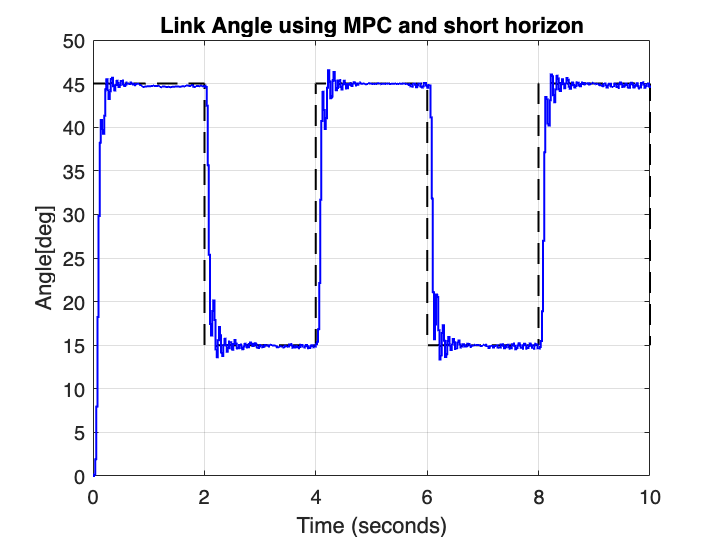

load('ref.mat')
load('filter_error.mat')
load('taskDLinkerror.mat')
load('taskDangle.mat')
load('QPSolver.mat')

plot(ref,'k--','LineWidth',1)
title('Link Angle using MPC and short horizon')
ylabel('Angle[deg]')
grid on
hold on
plot(taskDangle,'b','LineWidth',1)

hold off

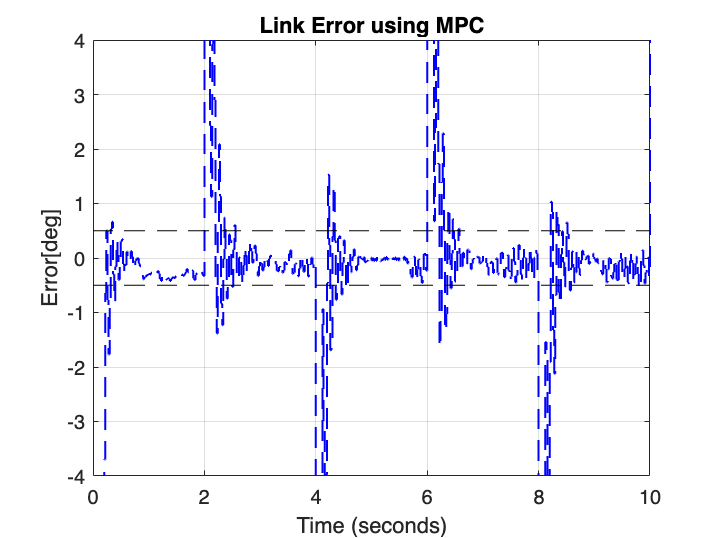


plot(taskDLinkerror,'b--','LineWidth',1)
grid on
title('Link Error using MPC')
ylabel('Error[deg]')
ylim([-4 4])
hold on
x = [0, 10];
y1 = [0.5, 0.5];
y2 = [-0.5, 0-.5];

plot(x, y1, 'k--');
plot(x, y2, 'k--');

hold off

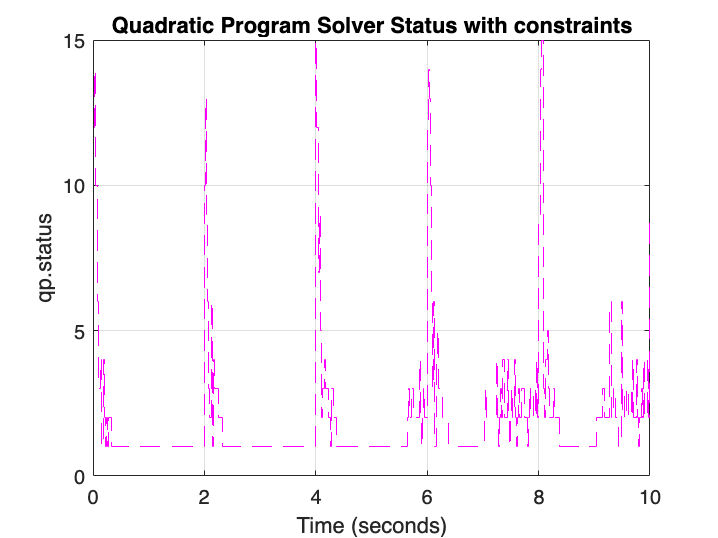


plot(QPsolver,'m--')
grid on
title('Quadratic Program Solver Status with constraints')